# Example 1: Analysis of a cellular structure (TPMS/Lattice)

## 1.1 Defining a unit cell parametrically

First the **type** of structure needs to be set - this sets how the equation is converted into a solid. 

- network' (default), creates a more skeletal/strut like structure at a target volume fraction. 

- 'surface' creates a thickened surface

- 'single' creates a skeletal/strut-like structure using a specified isovalue as an upper threshold

- 'double' is reccomended for more advanced users, and utilises a lower and upper isovalue to create a more wide range of structures

- 'lattice' can be used to generate node-strut based lattices by adding a thickness to struts and nodes

Next the structure **equation**, must be defined the most common TPMS-like functions can be accessed using their name, alternatively a matlab function equation, or lattice may be used.. 

- 'Primitive', 'Diamond', 'Gyroid', 'Neovius', 'IWP', 'FRD'. 

- Other example functions include 'Sphere', 'P-normCube' and 'Taurus'

- A lattice unit cell defined by the filepathname for the .txt file such as '*data/lattices/BCCXYZ.txt*'

- Alternatively, a custom **equation** can be defined such as: *equation = @(x,y,z) cos(x).*sin(y)+cos(y).*sin(z)+cos(z).*sin(x)+(2*y-1);*

Next the geometry parameters need to be defined, how these parameters are applied depends on the structure **type.**

- **network**-type structures can input a target volume fraction input as '**v1'**

- **surface**-type can input a target volume fraction '**v1**' around a mid-plane isovalue '**v2**'

- **single**-type directly inputs a single isovalue '**v1**' directly

- **double**-type uses '**v1**' and '**v2**' as the lower and upper bounding isovalues

- **lattice**-type structure directly use '**v1**' and '**v2**' to control the strut radius and node radius respectively

To create variable density/graded structures, either/both of **v1** and **v2** can be input as a single value or as a. Linear gradients along the x-axis should be input as an (Lx1) vector, 2D gradients should be an (LxM) matrix and 3D gradients should be (LxMxN) which will be remapped to stretch across bulk volume.

Additional inputs should also be defined, any inputs left blank will result in a default (safe) value being used. These values are the ordered inputs for the **TPMS** class constructor to create the TPMS object (**myTPMS**).

- The resolution for the meshgrid (**res**), in x,y,z

- the size of the unit cell (**sz**) in x,y,z

clear variables;
TYPE = "network"; % Types: "network","surface","single", "double", "lattice"
EQUATION = 'Gyroid'; %"Gyroid","Diamond","Primitive", "Neovius", "IWP", "FRD"
V1 = 0.5; % Geometry Parameter 1
V2 = 0; % Geometry Parameter 2
RES = [30 30 30]; % Resolution - (number of voxels per edge in x,y,z)
L = 1; % Unit cell size in mm
R = [0 0 0]; % Euler rotation defined as [Rx Ry Rz] in degrees
B = [0 0 0]; % Phase shift/translation [Bx By Bz] in mm
N = [1 1 1]; % Number of unit cells in X,Y,Z

% Use variables to define the bounding box/bulk size of the sample
VOLUME = bulkSize('box',L.*N);

% Use inputs to create the transform object
if verLessThan('matlab', '9.13') % Compatability for older versions of matlab
    TFORM = affine3d([L 0 0 B(1); 0 L 0 B(2); 0 0 L B(3); 0 0 0 1]'); % Definate an affine3d transform here using size and phase shift
else
    TFORM = simtform3d(L,R,B); % Other types of transforms can be defined - this example uses a similarity transform
end


% Create the unit cell: myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME);
% Any number of inputs may be left without an input: myCell = UnitCell();
% resulting in a gyroid network structure
myCell = UnitCell(TYPE,EQUATION,V1,V2,RES,TFORM,VOLUME);

## 1.2 Calculating the properties of the structure

After defining the structure, it must be generated and analysed.

Depending on the required properties, this involves potentially generating the following representations of the unit cell:

- a **v3field** object for storing 3D volumetric data/fields

- a **surfaceMesh** object which captures information about the boundary surface

- a **metrics** object is created to simplify the outputs to scalar values which can be used to rapidly compare properties of different structures.

To request calculation of properties, the **myTPMS.properties**(field,mechanical,surfaceMesh,curvaturemethod) method is used, the inputs turn on and off various calculation steps, which can skip steps if certain analysis information is not required. A boolean 1 or 0 will specify is this proeprty is required.

- **field**, is required for all subsequent operations with TPMS, this will automatically be turned on if later steps are requested

- **mechanical**, applies sets of periodic boundary conditions to create the cauchy stiffness tensor and homogenise the unit cell

- **surfaceMesh** requests that this be generated using matlab's inbuild isosurface function. 

- **curvature** allows the user to define which method which be used to approximate/calculate the curvature of the surface. The methods which have been included are '**trimesh2**', '**meyer2003**', '**kroon', 'implicit'** or 'none'. (more detailed explanations of these algrithms can be found in Ex2StlAnalysis.mlx)

Turning on more requested properties will increase the computational time - particulaly at higher resolutions. Many of these problems/algorithms have non-linear scaling so be careful when increasing resolution!

calcFields = 1;  % 1 or 0 to turn on or off.
calcMechanical = 1;  % 1 or 0 to turn on or off.
calcSurfaceMesh = 1; % 1 or 0 to turn on or off.
curvatureMethod = 'trimesh2'; % 'Curvature calculation method
myCell = myCell.compute(curvatureMethod,calcMechanical,calcSurfaceMesh); % Do the thing!

## 1.3 Plotting and visulisation

There are a range of different ways to plot/properties to visualse a generated structure. The syntax for using this function is **plot(TPMS,ax,plottype,property1,property2,opts).**

The **plottype** may be defined using any of the following:

- "surfaceMesh"(default),

- "voxel",

- "orthoslice",

- "slice",

- "histogram",

- "histogram2",

- "polemap",

- "tensor"

By default, the first input is the axis handle **ax** which the plot should be created on. This allows users to create the plots on subfigures. Below are examples showing how to create a new figure and use "gca" to select the current (just created) axis

Many of the plotting options can take inputs for setting which property/properties should be displayed as the colour of the figure.  To find the complete list of these the user can inspect the fields of the relevant data type the user can try the commands such as **myTPMS.F.property**, **myTPMS.FV.Fproperty** and **myTPMS.FV.Fproperty** to return the properties avaliables. Some of the common examples are below.

- [], monotone grey

- "inclination" Inclination angle

- "U" - Shows the value of the function (zero on the surface, non-zero on the end-caps)

When accessiong a property the property name (case-insensitive) will be compared to the first word. so calling "inclination", "Inclination" or "Inclination angle in deg^o" will all access the inclination property. The complete string passed in will become the label for the colorbar.

Voxel plot of property field 'U'

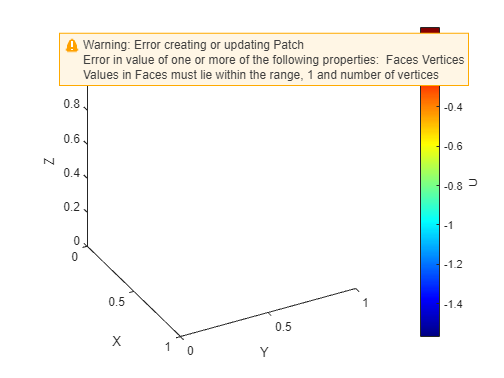

axesVoxel = myCell.plot("voxel","U");

Create orthosslice viewer - (Commented as this will pop up new window)

%axesSlice = myCell.plot("orthoslice","U");

XY-Slice of the TPMS function at a given z-height fraction

opts.slice = 25; % Define Z-slice height using options
axesXYslice = myCell.plot("slice","U",[],opts);

Rendering of the SurfaceMesh, coloured by a property

axesSurface = myCell.plot("SurfaceMesh","GC","vNormals");

Histogram shows the distribution of a property (will be area-weighted if a per-face value is used)

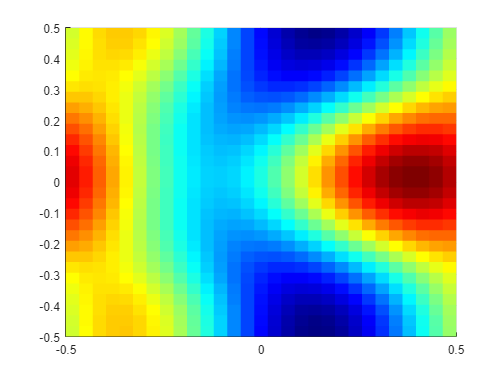

axesHist = myCell.plot("histogram","inclination angle");

2-Variable Histogram shows heatmap and how 2 properties interact

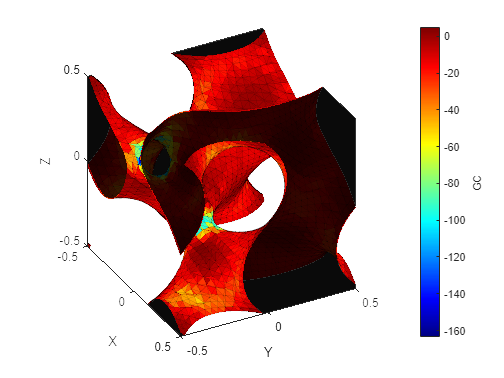

opts.n = 100; % Number of histogram bins

axesHist2 = myCell.plot("histogram2","inclination angle","GC mm^-^2");

Pole-map of surface orientations

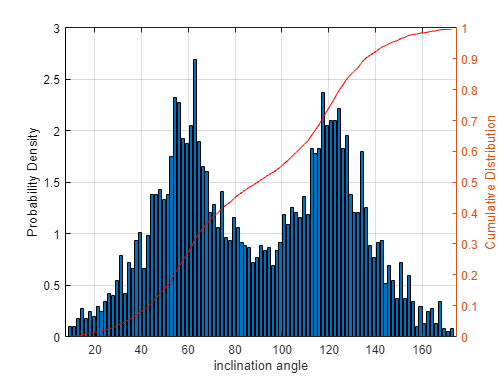

axesPolemap = myCell.plot("polemap");

Stiffness tensor representation showing relative elastic modulus compared to a solid cube (requires calculateMechanical to be turned on)

axesTensor = myCell.plot("tensor");

## 1.4 Exporting UnitCell data

There are a number of export options which have been integrated. An .INP file may be exported from the v3field. Or the surface may be exported as a .stl file. In future more options for exporting will be made avaliable.

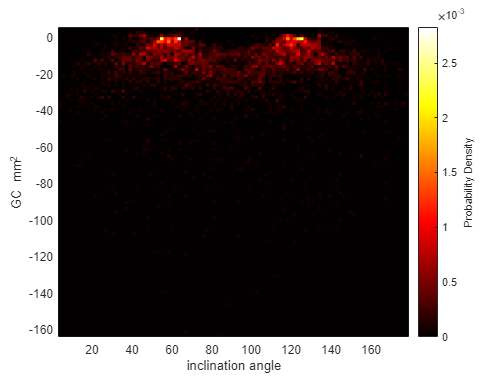

% myCell.F.exportINP('results/myTPMS.inp'); % INP Export (path+filename)

%myCell.FV.exportSTL('results/myTPMS.stl'); % STL Export (path+filename)

Once the properties have been calculated these various properties can be accessed and viewed using dot indexing or flattened to combine important metrics for the structure using TPMS.export.

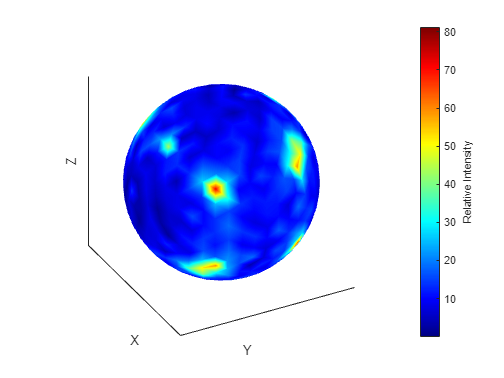

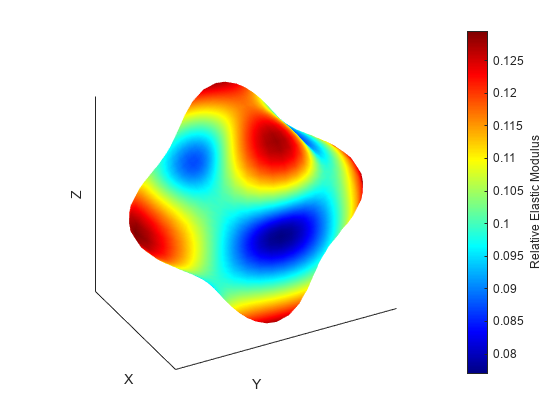

output = struct with fields:
           CPUtime: 5.8039
            Nfaces: 7584
            Nnodes: 4052
         errorFlag: 0
        meshVolume: -0.0228
    relativeVolume: 0.3608
       surfaceArea: 2.9248
      relativeArea: 0.4875
             rmsMC: 1.2581
             rmsGC: 22.5814
         thickness: 0.4667
      poreDiameter: 0.5735
       thicknessAM: 0.1944
           areaVar: 4.0853e-04
          areaMean: 0.3674
           areaStd: 0.0202
           areaMin: 0.3289
           areaMax: 0.3989
           elastic: 0.0769
           poisson: 0.1987
             shear: 0.0422
    totalStiffness: 0.1446
        zenerRatio: 1.3157
          equation: 'Gyroid'
              type: "network"
                v1: [0 1.2087 0]
                v2: 0
               res: 30
                Lx: 1
                Ly: 1
                Lz: 1


output = myCell.export